addpath('src', 'test', 'exp2')

Load Problem

[eqs, vars, pointKeys, pointValues] = problem.modifiedPendulum;
n = length(eqs);
eqs

$$eqs = \left(\begin{array}{c} \frac{\partial }{\partial t}x_{4}\left(t\right)-\cos\left(x_{3}\left(t\right)\right)\,x_{1}\left(t\right)\,x_{2}\left(t\right)\\ \frac{\partial }{\partial t}x_{5}\left(t\right)-\cos\left(x_{3}\left(t\right)\right)\,\sin\left(x_{3}\left(t\right)\right)\,{x_{2}\left(t\right)}^{2}+g\\ {\sin\left(x_{3}\left(t\right)\right)}^{2}\,{x_{2}\left(t\right)}^{2}+{x_{1}\left(t\right)}^{2}-1\\ -\tanh\left(x_{4}\left(t\right)-\frac{\partial }{\partial t}x_{1}\left(t\right)\right)\\ \sin\left(x_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}x_{2}\left(t\right)-x_{5}\left(t\right)+\cos\left(x_{3}\left(t\right)\right)\,x_{2}\left(t\right)\,\frac{\partial }{\partial t}x_{3}\left(t\right) \end{array}\right)$$

vars

$$vars(t) = \left(\begin{array}{ccccc} x_{1}\left(t\right) & x_{2}\left(t\right) & x_{3}\left(t\right) & x_{4}\left(t\right) & x_{5}\left(t\right) \end{array}\right)$$

Modify DAE

[eqs, vars, ~, ~, ~, pointKeys, pointValues] ...
            = preprocessDAE(eqs, vars, pointKeys, pointValues, 'Method', 'augmentation', 'Constants', 'sym');
eqs

$$eqs = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}x_{4}\left(t\right)-\cos\left(x_{3}\left(t\right)\right)\,x_{1}\left(t\right)\,x_{2}\left(t\right)\\ \frac{\partial }{\partial t}x_{5}\left(t\right)-\cos\left(x_{3}\left(t\right)\right)\,\sin\left(x_{3}\left(t\right)\right)\,{x_{2}\left(t\right)}^{2}+g\\ \sigma_{2}\,{x_{2}\left(t\right)}^{2}+{x_{1}\left(t\right)}^{2}-1\\ -\tanh\left(x_{4}\left(t\right)-\frac{\partial }{\partial t}x_{1}\left(t\right)\right)\\ \mathrm{constDx2t}\,\sin\left(x_{334}\left(t\right)\right)-x_{5}\left(t\right)+{\mathrm{constx}}_{2}\,\cos\left(x_{334}\left(t\right)\right)\,{\mathrm{Dx3t}}_{1}\left(t\right)\\ 2\,\mathrm{constDx2t}\,\sigma_{2}\,x_{2}\left(t\right)+2\,\cos\left(x_{3}\left(t\right)\right)\,\mathrm{Dx3t}\left(t\right)\,\sin\left(x_{3}\left(t\right)\right)\,{x_{2}\left(t\right)}^{2}+2\,\mathrm{Dx1t}\left(t\right)\,x_{1}\left(t\right)\\ -\tanh\left(x_{4}\left(t\right)-\mathrm{Dx1t}\left(t\right)\right)\\ {{\mathrm{constx}}_{2}}^{2}\,\sigma_{1}+{x_{1}\left(t\right)}^{2}-1\\ 2\,\cos\left(x_{334}\left(t\right)\right)\,{\mathrm{Dx3t}}_{1}\left(t\right)\,{{\mathrm{constx}}_{2}}^{2}\,\sin\left(x_{334}\left(t\right)\right)+2\,\mathrm{constDx2t}\,{\mathrm{constx}}_{2}\,\sigma_{1}+2\,{\mathrm{Dx1t}}_{1}\left(t\right)\,x_{1}\left(t\right)\\ -\tanh\left(x_{4}\left(t\right)-{\mathrm{Dx1t}}_{1}\left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\sin\left(x_{334}\left(t\right)\right)}^{2}\\ \sigma_{2}={\sin\left(x_{3}\left(t\right)\right)}^{2} \end{array}$$

[eqs, vars, ~, pointKeys, pointValues] = reduceIndex(eqs, vars, pointKeys, pointValues);
[eqs, vars] = reduceDifferentialOrder(eqs, vars);

Convert to MATLAB Function handles

pDAEs = symvar(eqs);
pDAEvars = symvar(vars);
extraParams = setdiff(pDAEs, pDAEvars);
extraParamValues = num2cell(substitutePoint(extraParams, pointKeys, pointValues));
extraParams = num2cell(extraParams);

f = daeFunction(eqs, vars, extraParams{:});
F = @(t, Y, YP) f(t, Y, YP, extraParamValues{:});
jac = daeJacobianFunction(eqs, vars, extraParams{:});
Jac = @(t, Y, YP) jac(t, Y, YP, extraParamValues{:});

Consistent initialization

opt = odeset('Jacobian', Jac, 'RelTol', 1e-8, 'AbsTol', 1e-8);

Unrecognized function or variable 'Jac'.

[y0est, yp0est] = extractVariableValue(vars, pointKeys, pointValues, 'MissingVariable', 'zero');
[y0, yp0] = decic(F, 0, y0est.', [], yp0est.', [], opt);
y0
yp0

Solve the DAE

tspan = [0 10];
sol = ode15i(F, tspan, y0, yp0, opt);

Plot the solution

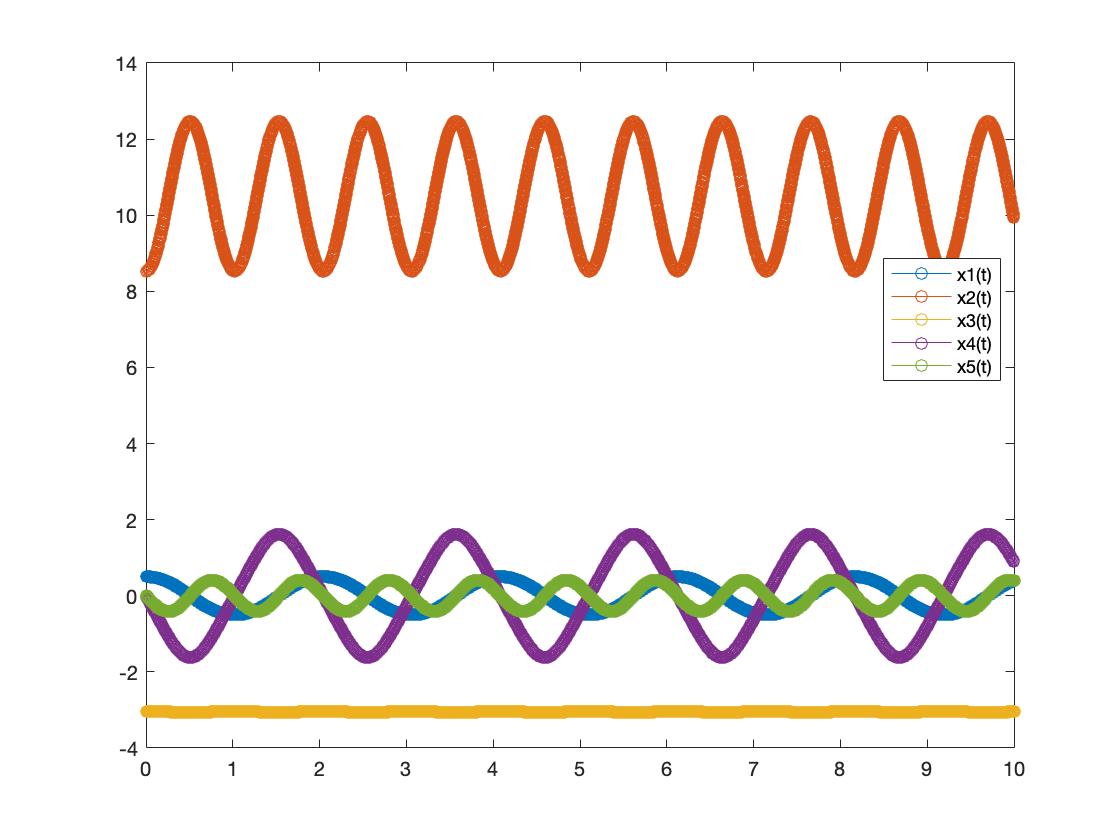

plot(sol.x, sol.y(1:n, :), '-o');
for k = 1:n
    S{k} = char(vars(k));
end
legend(S, 'Location', 'Best')

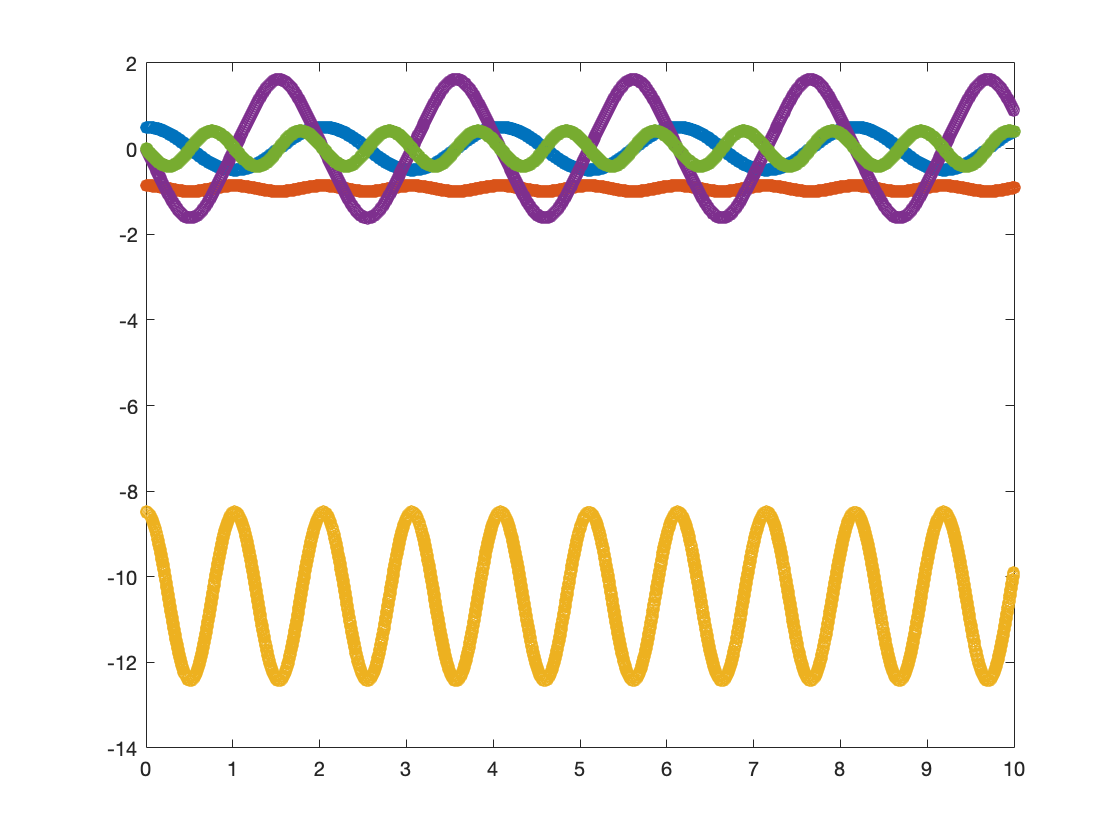

back = @(y) [y(1); y(2) * sin(y(3)); y(2) * cos(y(3)); y(4); y(5)];
sol_back = cell2mat(cellfun(back, num2cell(sol.y, 1), 'UniformOutput', false));
plot(sol.x, sol_back, '-o')

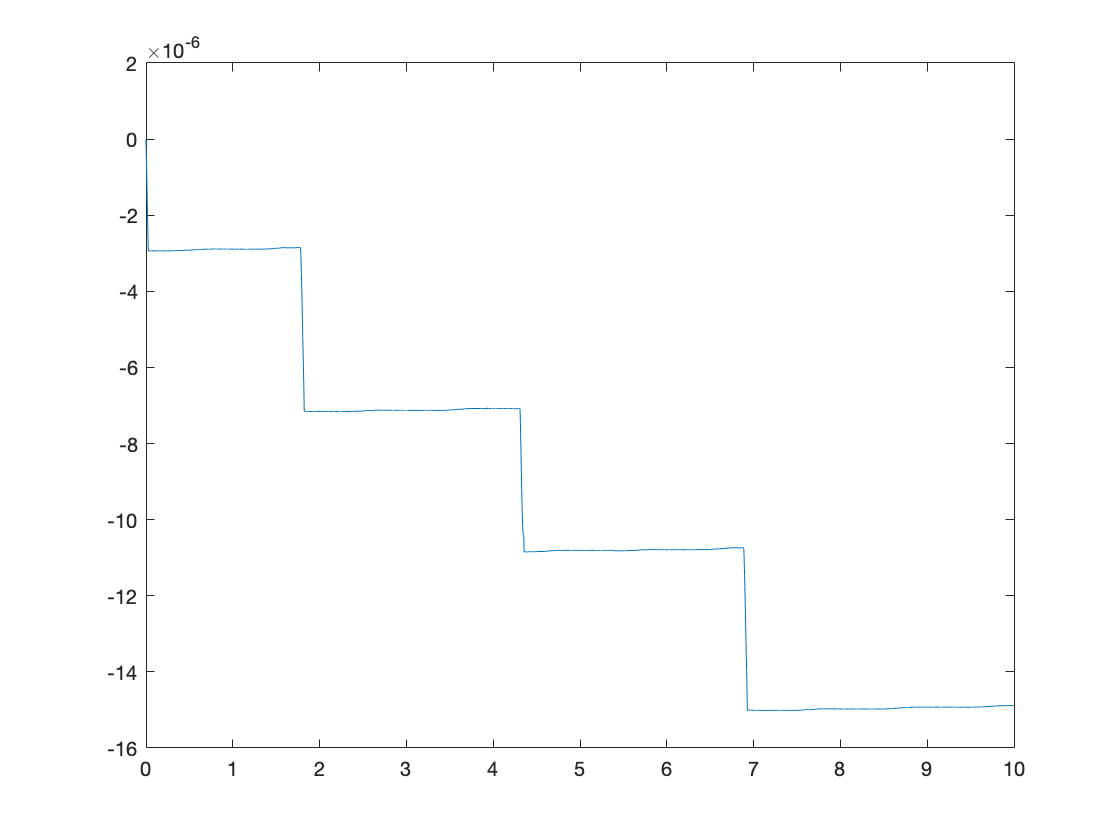

initial_energy = -9.8 * cos(pi/6);
energy = @(y) 9.8 * y(2) + 0.5 * (y(4)^2 + y(5)^2) - initial_energy;
d_energy = cell2mat(cellfun(energy, num2cell(sol_back, 1), 'UniformOutput', false));
plot(sol.x, d_energy);

format long
sol_back(1:n, end)

ans =    0.406637380329034
  -0.913589645800562
  -9.885407901218493
   0.882089312306304
   0.392616629161824
